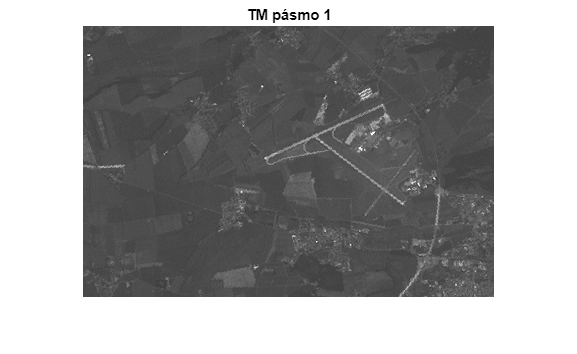

clc; clear; close all;

prompt = "Zadej první pásmo Landsat TM (1 - 4): ";
Tx1=num2str(input(prompt));
T=['Landsat\LANDSAT_sub_',Tx1,'.tif'];
L1=imread(T);
prompt = "Zadej druhé pásmo Landsat TM (1 - 4): ";
Tx2=num2str(input(prompt));
T=['Landsat\LANDSAT_sub_',Tx2,'.tif'];
L2=imread(T);

[m,n]=size(L1);

imshow(L1)
T=['TM pásmo ' Tx1];
title(T)

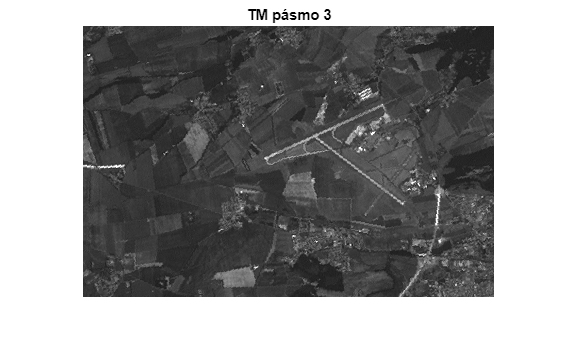

figure
imshow(L2)
T=['TM pásmo ' Tx2];
title(T)


V1 = reshape(L1,[1,m*n]);
V2 = reshape(L2,[1,m*n]);
V1=double(V1);
V2=double(V2);

P(:,1)=V1-mean(V1);
P(:,2)=V2-mean(V2);

disp('kovarianční matice');

kovarianční matice


S=cov(P)

S =   156.0608  254.9157
  254.9157  489.3804


disp('korelační matice');

korelační matice


R=corrcoef(P)

R =     1.0000    0.9224
    0.9224    1.0000


[V,D] = eig(S);

[d,ind] = sort(diag(D),'descend');
disp('vlastní čísla kovarianční matice');

vlastní čísla kovarianční matice


Ds = D(ind,ind)

Ds =   627.2818         0
         0   18.1594


disp('vlastní vektory kovarianční matice');

vlastní vektory kovarianční matice


Vs = V(:,ind)

Vs =     0.4758   -0.8795
    0.8795    0.4758


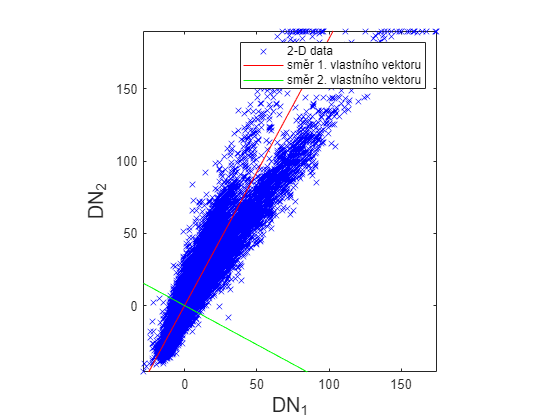

pc=Vs;

P_rot = P*pc;

figure
plot(P(:,1), P(:,2), 'bx')
axis equal;
hold on;
line([min(P(:,1)),max(P(:,1))], [min(P(:,1))*pc(2,1)/pc(1,1),max(P(:,1))*pc(2,1)/pc(1,1)], 'Color', [1 0 0]);
hold on;
line([min(P(:,1)),max(P(:,1))], [min(P(:,1))*pc(2,2)/pc(1,2),max(P(:,1))*pc(2,2)/pc(1,2)], 'Color', [0 1 0]);
legend('2-D data','směr 1. vlastního vektoru','směr 2. vlastního vektoru');
xlabel('DN_1','FontSize',15); ylabel('DN_2', 'FontSize',15);
hold off
axis([min(P(:,1)) max(P(:,1)) min(P(:,2)),max(P(:,2))])

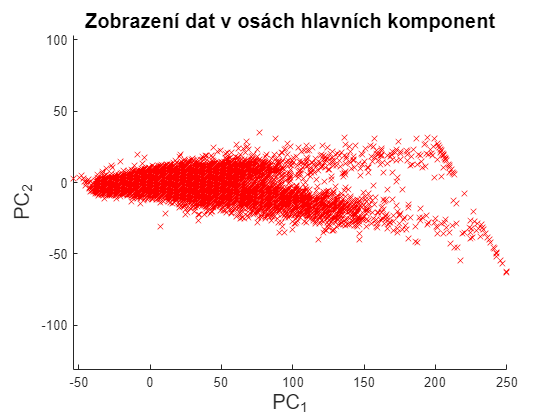


figure;
scatter(P_rot(:,1), P_rot(:,2), 'rx');
title('Zobrazení dat v osách hlavních komponent', 'FontSize',15);
xlabel('PC_1','FontSize',15); ylabel('PC_2', 'FontSize',15);
axis equal;


disp('informační obsah první komponenty');

informační obsah první komponenty


d(1)/sum(d)

ans = 0.9719

disp('informační obsah druhé komponenty');

informační obsah druhé komponenty


d(2)/sum(d)

ans = 0.0281

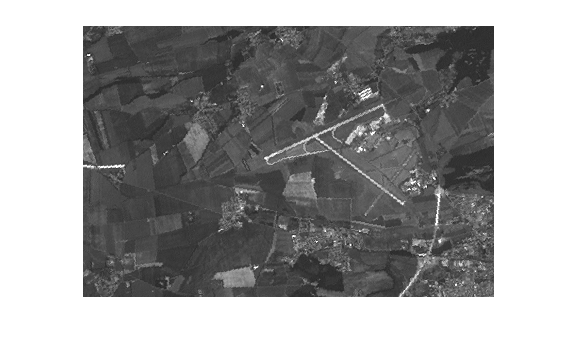


figure;
C1=reshape(P_rot(:,1)+mean(V1),[m,n]);
imshow(uint8(C1))

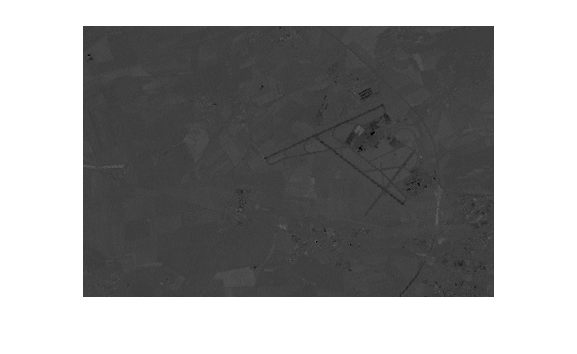

figure;
C2=reshape(P_rot(:,2)+mean(V2),[m,n]);
imshow(uint8(C2))